# MPC Homework Two

% January 19, 2020.
% Author: Lucky Yerimah
clc; % clear all previous variables

A = [-1, 0, 0; 1, -1, 0; 0, 1, -1];
B = [1;0;0];
C = [0,0,1];
D = 0;

## Problem One

sys = ss(A,B,C,D); % converting matrices to state space 
Gs = tf(sys) % Continuous-time transfer function


Gs =
 
            1
  ---------------------
  s^3 + 3 s^2 + 3 s + 1
 
Continuous-time transfer function.



Gz = c2d(Gs,0.5) % Discrete-time transfer function


Gz =
 
  0.01439 z^2 + 0.03973 z + 0.006794
  ----------------------------------
  z^3 - 1.82 z^2 + 1.104 z - 0.2231
 
Sample time: 0.5 seconds
Discrete-time transfer function.



P = pole(Gz) % to determine the poles of the discrete transfer function

P =    0.6065 + 0.0000i
   0.6065 - 0.0000i
   0.6065 + 0.0000i


Z = zero(Gz) % to determine the zeros of the discrete transfer function

Z =    -2.5785
   -0.1831


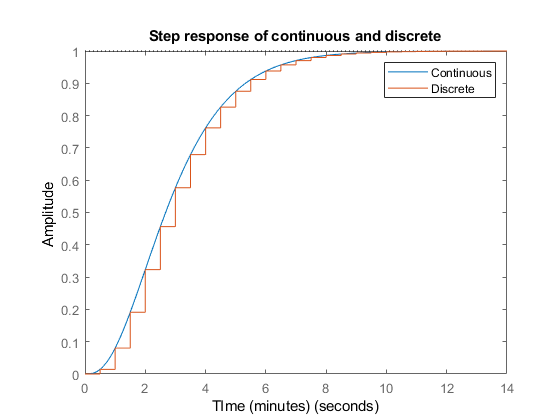

figure(1)
step(Gs,Gz) % to produce a step response of both transfer function
title("Step response of continuous and discrete"); 
legend("Continuous","Discrete");
xlabel('TIme (minutes)')

## Problem Two

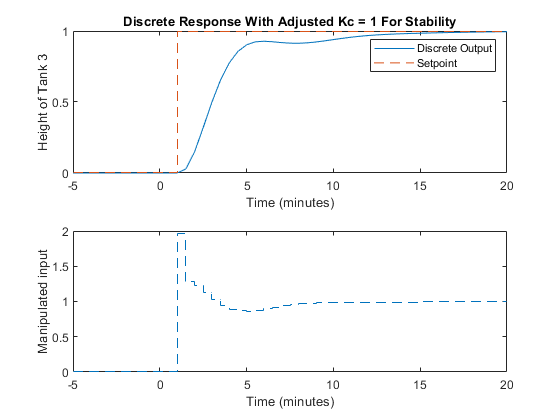

deltaT = 0.5; % sample time in minutes
x0 = [0,0,0]; % initial conditions
time = (-5:0.5:20); % time vector in minutes

% initial conditions for the output,setpoint,error and manipulated input
% all variables were increased by additional 3 to compensate for negative
% indices
y =  zeros(1,length(time)+3);
r = zeros(1,length(time)+3);
error = zeros(1,length(time)+3);
u = zeros(1,length(time)+3);

% PID parameters
ti = 3; % minutes
td = 0.4; % minutes
kc = 1; % minutes

for j = 1:length(time); % step change at time = 0
    if time(j) < 1;
        r(j+3) = 0;
    else 
        r(j+3) = 1;
    end
    error = r - y;
    % IMC based PID function created to compute manipulated input
    u(j+3) = IMC_PID(u(j+2),error(j+3),error(j+2),error(j+1),kc,ti,td,deltaT); 

[~,xnew] = ode45(@(t,x) plantmodel(t,x,u(j+3)),[time(j) time(j)+deltaT], x0); % ODE45 function
y(j+4) = xnew(end,end); % output as last value of xnew
x0= xnew(end,:)'; % assigning states variables as input for next iteration
end

% Plots 
figure(2)
subplot(2,1,1)
plot(time,y(4:end-1))
hold on
stairs(time,r(4:end),'--')
hold off
xlabel('Time (minutes)')
ylabel('Height of Tank 3')
legend('Discrete Output','Setpoint')
title('Discrete Response With Adjusted Kc = 1 For Stability')

subplot(2,1,2)
stairs(time,u(4:end),'--')
xlabel('Time (minutes)')
ylabel('Manipulated input')

## Problem Three (Part A)

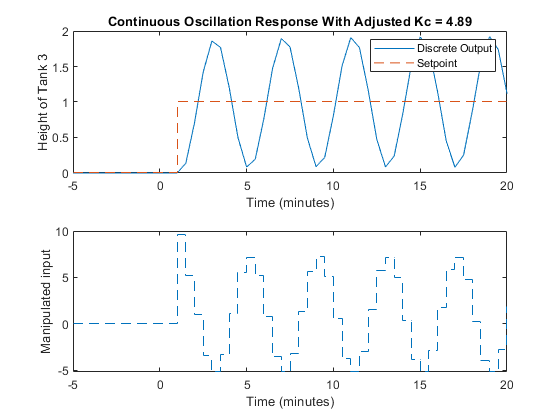

% Kc adjusted until continuous oscillation was observed

clear all % clear all previous variables
deltaT = 0.5; % sample time in minutes
x0 = [0,0,0]; % initial conditions
time = (-5:0.5:20); % time vector in minutes

% initial conditions for the output,setpoint,error and manipulated input
% all variables were increased by additional 3 to compensate for negative
% indices
y =  zeros(1,length(time)+3);
r = zeros(1,length(time)+3);
error = zeros(1,length(time)+3);
u = zeros(1,length(time)+3);

% PID parameters
ti = 3; % minutes
td = 0.4; % minutes
kc = 4.89; % Adjusted Kc (minutes)

for j = 1:length(time); % step change at time = 0
    if time(j) < 1;
        r(j+3) = 0;
    else 
        r(j+3) = 1;
    end
    error = r - y;
    % IMC based PID function created to compute manipulated input
    u(j+3) = IMC_PID(u(j+2),error(j+3),error(j+2),error(j+1),kc,ti,td,deltaT); 

[~,xnew] = ode45(@(t,x) plantmodel(t,x,u(j+3)),[time(j) time(j)+deltaT], x0); % ODE45 function
y(j+4) = xnew(end,end); % output as last value of xnew
x0= xnew(end,:)'; % assigning states variables as input for next iteration
end

% Plots 
figure(2)
subplot(2,1,1)
plot(time,y(4:end-1))
hold on
stairs(time,r(4:end),'--')
hold off
xlabel('Time (minutes)')
ylabel('Height of Tank 3')
legend('Discrete Output','Setpoint')
title('Continuous Oscillation Response With Adjusted Kc = 4.89')

subplot(2,1,2)
stairs(time,u(4:end),'--')
xlabel('Time (minutes)')
ylabel('Manipulated input')

## Problem Three (Part B)

% Computing the poles of the closed loop system using new Kc value
A = [-1, 0, 0; 1, -1, 0; 0, 1, -1];
B = [1;0;0];
C = [0,0,1];
D = 0;

sys = ss(A,B,C,D); % converting matrices to state space 
Gs = tf(sys); % Continuous-time transfer function
Gz = c2d(Gs,0.5)% Discrete-time transfer function


Gz =
 
  0.01439 z^2 + 0.03973 z + 0.006794
  ----------------------------------
  z^3 - 1.82 z^2 + 1.104 z - 0.2231
 
Sample time: 0.5 seconds
Discrete-time transfer function.



[NumG, DimG, Tsample] = tfdata(Gz,'v') % extractiong the numerator and denominator of process transfer function

NumG =          0    0.0144    0.0397    0.0068


DimG =     1.0000   -1.8196    1.1036   -0.2231


Tsample = 0.5000


% Controller parameters 
ti = 3; 
td = 0.4;
kc = 4.89;
deltaT = 0.5;

b1 = -kc*(1+(2*td/deltaT));
b2 = kc*(1+(deltaT/ti) + (td/deltaT));
b0 = kc*td/deltaT; 


CNum = [b2, b1, b0]; % controller numerator transfer function
CDim = [1,-1,0]; % controller denominator transfer function

% multiplying numerator and denominator tranfer function of the process and
% controller to create the closed loop tranfer function
Num_cl = conv(CNum,NumG); 
Dim_cl = conv(CDim,DimG);

G_system = Num_cl + Dim_cl % z domain transfer function of closed loop system

G_system =     1.0000   -2.6812    3.1224   -1.7103    0.2922    0.0266


Closed_loop_poles = roots(G_system) % closed loop poles

Closed_loop_poles =    0.7046 + 0.7099i
   0.7046 - 0.7099i
   0.8449 + 0.0000i
   0.4912 + 0.0000i
  -0.0640 + 0.0000i


abs(Closed_loop_poles) % absolute values of poles

ans =     1.0002
    1.0002
    0.8449
    0.4912
    0.0640



% all poles are still within the unit circle.

## Problem Four (Part A)

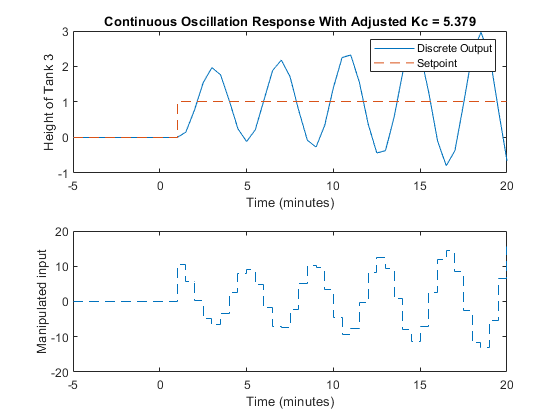

% Kc value increased by 10 percent

clear all % clear all previous variables
deltaT = 0.5; % sample time in minutes
x0 = [0,0,0]; % initial conditions
time = (-5:0.5:20); % time vector in minutes

% initial conditions for the output,setpoint,error and manipulated input
% all variables were increased by additional 3 to compensate for negative
% indices
y =  zeros(1,length(time)+3);
r = zeros(1,length(time)+3);
error = zeros(1,length(time)+3);
u = zeros(1,length(time)+3);

% PID parameters
ti = 3; % minutes
td = 0.4; % minutes
kc = 5.379; % Adjusted Kc (minutes)

for j = 1:length(time); % step change at time = 0
    if time(j) < 1;
        r(j+3) = 0;
    else 
        r(j+3) = 1;
    end
    error = r - y;
    % IMC based PID function created to compute manipulated input
    u(j+3) = IMC_PID(u(j+2),error(j+3),error(j+2),error(j+1),kc,ti,td,deltaT); 

[~,xnew] = ode45(@(t,x) plantmodel(t,x,u(j+3)),[time(j) time(j)+deltaT], x0); % ODE45 function
y(j+4) = xnew(end,end); % output as last value of xnew
x0= xnew(end,:)'; % assigning states variables as input for next iteration
end

% Plots 
figure(2)
subplot(2,1,1)
plot(time,y(4:end-1))
hold on
stairs(time,r(4:end),'--')
hold off
xlabel('Time (minutes)')
ylabel('Height of Tank 3')
legend('Discrete Output','Setpoint')
title('Continuous Oscillation Response With Adjusted Kc = 5.379')

subplot(2,1,2)
stairs(time,u(4:end),'--')
xlabel('Time (minutes)')
ylabel('Manipulated input')

## Problem Four (Part B)

% Computing the poles of the closed loop system using new Kc value
A = [-1, 0, 0; 1, -1, 0; 0, 1, -1];
B = [1;0;0];
C = [0,0,1];
D = 0;

sys = ss(A,B,C,D); % converting matrices to state space 
Gs = tf(sys); % Continuous-time transfer function
Gz = c2d(Gs,0.5)% Discrete-time transfer function


Gz =
 
  0.01439 z^2 + 0.03973 z + 0.006794
  ----------------------------------
  z^3 - 1.82 z^2 + 1.104 z - 0.2231
 
Sample time: 0.5 seconds
Discrete-time transfer function.



[NumG, DimG, Tsample] = tfdata(Gz,'v') % extractiong the numerator and denominator of process transfer function

NumG =          0    0.0144    0.0397    0.0068


DimG =     1.0000   -1.8196    1.1036   -0.2231


Tsample = 0.5000


% Controller parameters 
ti = 3; 
td = 0.4;
kc = 5.379;
deltaT = 0.5;

b1 = -kc*(1+(2*td/deltaT));
b2 = kc*(1+(deltaT/ti) + (td/deltaT));
b0 = kc*td/deltaT; 


CNum = [b2, b1, b0]; % controller numerator transfer function
CDim = [1,-1,0]; % controller denominator transfer function

% multiplying numerator and denominator tranfer function of the process and
% controller to create the closed loop tranfer function
Num_cl = conv(CNum,NumG); 
Dim_cl = conv(CDim,DimG);

G_system = Num_cl + Dim_cl % z domain transfer function of closed loop system

G_system =     1.0000   -2.6674    3.1423   -1.7487    0.2991    0.0292


Closed_loop_poles = roots(G_system) % closed loop poles

Closed_loop_poles =    0.7001 + 0.7442i
   0.7001 - 0.7442i
   0.8439 + 0.0000i
   0.4909 + 0.0000i
  -0.0676 + 0.0000i


abs(Closed_loop_poles) % absolute values of poles

ans =     1.0217
    1.0217
    0.8439
    0.4909
    0.0676



% Some of the poles are already beyond the unit circle, thus indicating the
% onset of instability.

## Plant function

function xdot = plantmodel(t,x,u)
% State space equations 
xdot(1) = -x(1) + u;
xdot(2) = x(1) - x(2);
xdot(3) = x(2) - x(3);

xdot = xdot'; % converting the ODEs to column vector

end

## IMC Based PID function

function uk = IMC_PID(uk2,rk3,rk2,rk1,kc,ti,td,deltaT)

b1 = -kc*(1+(2*td/deltaT));
b2 = kc*(1+(deltaT/ti) + (td/deltaT));
b0 = kc*td/deltaT; 

uk = uk2 + b2*rk3 + b1*rk2 + b0*rk1;
end